# Code for the Merging of the Rockall Trough Eastern Boundary

## MicroCAT Data

***Original authors: Paul Wright, March 2010 (Updated Ben Moat, March and Nov 2012)***

The selcted P, S and T data are obtained from the mooring .microcat files and interpolated onto the full timeseries time grid, sorted into pressure levels and then gridded. uses meta data files to select the MicroCATs. it would be possible to simplify this further but it is debatable whether it may be better to leave a bit "open" for the ease of updating on an annual basis.  Clearer too.

Notes specific to each deployment period are included within the loops.

### Code History

- 16 April 2010 - Code eb_merging_v1.m written and generally functioning well.  Some issues at the joins between the deployment periods and the occasional spkie to get rid of. Issue with the gridding not stopping the same way as hydro_grid_merge.m

- 16 April 2010 - changed code to read the gridded files rather than the microcat files, as they have been individually worked on and repaired, corrected and de-spiked where necessary... now eb_merging_v2.m

- 19 April 2010 - removed final data point of each MicroCAT to attempt to remove the spiking at the joins between the deployments.

- 26 May 2010 - changed gridded function to con_tprof_v3.m which stops the gridding at the upper MicroCAT.  Interpolates over data gaps less than a year in order to match Kanzow's original code and present data for the MOC code.

- 9 June 2010 - PGW changed the climatology TSclim

- 28 June 2010 - changed climatology back to original.  Updated to include D344 data

- 11 August 2010 - Tidied up and improved comments slightly

- June 2011 - Updated merging Apr 2009 - Dec 2010

- Sept 2013 - added in name of cliamtology (e.g. hbase or argo)

- Jan 2017 - Adapted for OSNAP mooring (by L. Houpert)


if exist('moor','var')
else
    moor{1} = 'rteb_osnap_01_2014';
    moor{2} = 'rteb_osnap_02_2015';
    moor{3} = 'rteb_osnap_03_2016';
    moor{4} = 'rteb_osnap_04_2017';
    moor{5} = 'rteb_osnap_05_2018';
end

col         = {'r','b','m','c','g','y','r--','b--','m--','c--','g--','y--','r:',...
    'b:','m:','c:','g:','y:','r.','b.','m.','c.','g.','y.','r'};

[~,idx]=unique(cell2mat(moor),'rows');
moor =  moor(idx,:);



### OSNAP 1 (PE399 --> DY053)


disp('---------  OSNAP 1 (KN221 --> PE399) ---------')

---------  OSNAP 1 (KN221 --> PE399) ---------


fileID1 = fopen([boundarydir, moor{1}, '.dat']);
delimiter = {'\t',' '};
startRow = 6;
% % Format string for each line of text:
%   column1: text (%s)
%	column2: double (%f)
%   column3: double (%f)
%	column4: double (%f)
%   column5: double (%f)
% For more information, see the TEXTSCAN documentation.
formatSpec = '%s%f%f%f%f%*s%*s%[^\n\r]';
% % Read columns of data according to format string.
% This call is based on the structure of the file used to generate this
% code. If an error occurs for a different file, try regenerating the code
% from the Import Tool.
file1_data = textscan(fileID1, formatSpec, 'Delimiter', delimiter, 'MultipleDelimsAsOne', true, 'HeaderLines' ,startRow-1, 'ReturnOnError', false);
% % Close the text file.
fclose(fileID1);
mooring1 = file1_data{1};
sn1      = file1_data{2};
mc1      = file1_data{3};
z1       = file1_data{4};
lon1     = file1_data{5};

T1 = zeros(length(sn1), length(JG));
P1 = zeros(length(sn1), length(JG));
S1 = zeros(length(sn1), length(JG));

i = 1; j = 1;
for i = 1: length(sn1)
    
    infile = [hydrodir, mooring1{i,:}, '_grid.mat'];
    load(infile);
    jdnew = datenum(gregorian(jd));    
    sampling_rate = round(1./median(diff(jd_grid))); %nominal sampling rate [per day]
    salinity    = interp1(jdnew(1:end-1), Sfs(mc1(i),1:end-1)', JG)';
    temp        = interp1(jdnew(1:end-1), Tfs(mc1(i),1:end-1)', JG)';
    pressure    = interp1(jdnew(1:end-1), Pfs(mc1(i),1:end-1)', JG)';
    Sfs1(j,:) = salinity;
    Pfs1(j,:) = pressure;
    Tfs1(j,:) = temp;
    
    j = j + 1;
    
    if mc_check_plot
        figure(20011)
        hold on; box on;
        plot(JG, Sfs1(i, :), col{:,i},'LineWidth',2);
        title('OSNAP 2 - SALINITY')
        
        figure(20012)
        hold on; box on;
        plot(JG, Tfs1(i, :), col{:,i},'LineWidth',2);
        title('OSNAP 2 - TEMPERATURE')
        
        figure(200120)
        hold on; box on;
        plot(JG, sw_pden(Sfs1(i, :),Tfs1(i, :),Pfs1(i, :),0)-1000, col{:,i},'LineWidth',2);
        title('OSNAP 1 - POTENTIAL DENSITY')      
        
        figure(20013)
        hold on; box on;
        plot(JG, Pfs1(i, :), col{:,i},'LineWidth',2);
        title('OSNAP 1 - PRESSURE')
        
    end
    
end


### OSNAP 2 (PE399 --> DY053)

disp('---------  OSNAP 2 (PE399 --> DY053) ---------')

---------  OSNAP 2 (PE399 --> DY053) ---------


fileID2 = fopen([boundarydir, moor{2}, '.dat']);
delimiter = {'\t',' '};
startRow = 6;
% % Format string for each line of text:
%   column1: text (%s)
%	column2: double (%f)
%   column3: double (%f)
%	column4: double (%f)
%   column5: double (%f)
% For more information, see the TEXTSCAN documentation.
formatSpec = '%s%f%f%f%f%*s%*s%[^\n\r]';
% % Read columns of data according to format string.
% This call is based on the structure of the file used to generate this
% code. If an error occurs for a different file, try regenerating the code
% from the Import Tool.
file2_data = textscan(fileID2, formatSpec, 'Delimiter', delimiter, 'MultipleDelimsAsOne', true, 'HeaderLines' ,startRow-1, 'ReturnOnError', false);
% % Close the text file.
fclose(fileID2);
mooring2 = file2_data{1};
sn2      = file2_data{2};
mc2      = file2_data{3};
z2       = file2_data{4};
lon2     = file2_data{5};

T2 = zeros(length(sn2), length(JG));
P2 = zeros(length(sn2), length(JG));
S2 = zeros(length(sn2), length(JG));

i = 1; j = 1;
for i = 1: length(sn2)
    
    infile = [hydrodir, mooring2{i,:}, '_grid.mat'];
    load(infile);
    jdnew = datenum(gregorian(jd));    
    sampling_rate = round(1./median(diff(jd_grid))); %nominal sampling rate [per day]
    salinity    = interp1(jdnew(1:end-1), Sfs(mc2(i),1:end-1)', JG)';
    temp        = interp1(jdnew(1:end-1), Tfs(mc2(i),1:end-1)', JG)';
    pressure    = interp1(jdnew(1:end-1), Pfs(mc2(i),1:end-1)', JG)';
    Sfs2(j,:) = salinity;
    Pfs2(j,:) = pressure;
    Tfs2(j,:) = temp;
    
    j = j + 1;
    
    if mc_check_plot
        figure(20021)
        hold on; box on;
        plot(JG, Sfs2(i, :), col{:,i},'LineWidth',2);
        title('OSNAP 2 - SALINITY')
        
        figure(20022)
        hold on; box on;
        plot(JG, Tfs2(i, :), col{:,i},'LineWidth',2);
        title('OSNAP 2 - TEMPERATURE')
        
        figure(200220)
        hold on; box on;
        plot(JG, sw_pden(Sfs2(i, :),Tfs2(i, :),Pfs2(i, :),0)-1000, col{:,i},'LineWidth',2);
        title('OSNAP 2 - POTENTIAL DENSITY')      
    
        figure(20023)
        hold on; box on;
        plot(JG, Pfs2(i, :), col{:,i},'LineWidth',2);
        title('OSNAP 2 - PRESSURE')
    end
    
end


### OSNAP 3 (DY053 --> DY078)


disp('---------  OSNAP 3 (DY053--> DY078) ---------')

---------  OSNAP 3 (DY053--> DY078) ---------


fileID3 = fopen([boundarydir, moor{3}, '.dat']);
delimiter = {'\t',' '};
startRow = 6;
% % Format string for each line of text:
%   column1: text (%s)
%	column2: double (%f)
%   column3: double (%f)
%	column4: double (%f)
%   column5: double (%f)
% For more information, see the TEXTSCAN documentation.
formatSpec = '%s%f%f%f%f%*s%*s%[^\n\r]';
% % Read columns of data according to format string.
% This call is based on the structure of the file used to generate this
% code. If an error occurs for a different file, try regenerating the code
% from the Import Tool.
file3_data = textscan(fileID3, formatSpec, 'Delimiter', delimiter, 'MultipleDelimsAsOne', true, 'HeaderLines' ,startRow-1, 'ReturnOnError', false);
% % Close the text file.
fclose(fileID3);
mooring3 = file3_data{1};
sn3      = file3_data{2};
mc3      = file3_data{3};
z3       = file3_data{4};
lon3     = file3_data{5};

T3 = zeros(length(sn3), length(JG));
P3 = zeros(length(sn3), length(JG));
S3 = zeros(length(sn3), length(JG));

i = 1; j = 1;
for i = 1: length(sn3)
    
    infile = [hydrodir, mooring3{i,:}, '_grid.mat'];
    load(infile);
    jdnew = datenum(gregorian(jd));    
    sampling_rate = round(1./median(diff(jd_grid))); %nominal sampling rate [per day]
    salinity    = interp1(jdnew(1:end-1), Sfs(mc3(i),1:end-1)', JG)';
    temp        = interp1(jdnew(1:end-1), Tfs(mc3(i),1:end-1)', JG)';
    pressure    = interp1(jdnew(1:end-1), Pfs(mc3(i),1:end-1)', JG)';
    Sfs3(j,:) = salinity;
    Pfs3(j,:) = pressure;
    Tfs3(j,:) = temp;
    
    j = j + 1;
    
    if mc_check_plot
        figure(30021)
        hold on; box on;
        plot(JG, Sfs3(i, :), col{:,i},'LineWidth',2);
        title('OSNAP 3 - SALINITY')
        
        figure(30022)
        hold on; box on;
        plot(JG, Tfs3(i, :), col{:,i},'LineWidth',2);
        title('OSNAP 3 - TEMPERATURE')
        
        figure(300220)
        hold on; box on;
        plot(JG, sw_pden(Sfs3(i, :),Tfs3(i, :),Pfs3(i, :),0)-1000, col{:,i},'LineWidth',2);
        title('OSNAP 3 - POTENTIAL DENSITY')      
    
        figure(30023)
        hold on; box on;
        plot(JG, Pfs3(i, :), col{:,i},'LineWidth',2);
        title('OSNAP 3 - PRESSURE')
    end
    
end



### OSNAP 4 (DY078 --> AR30)


disp('---------  OSNAP 4 (DY078--> AR30) ---------')

---------  OSNAP 4 (DY078--> AR30) ---------


fileID4 = fopen([boundarydir, moor{4}, '.dat']);
delimiter = {'\t',' '};
startRow = 6;
formatSpec = '%s%f%f%f%f%*s%*s%[^\n\r]';
file4_data = textscan(fileID4, formatSpec, 'Delimiter', delimiter, 'MultipleDelimsAsOne', true, 'HeaderLines' ,startRow-1, 'ReturnOnError', false);
% % Close the text file.
fclose(fileID4);
mooring4 = file4_data{1};
sn4      = file4_data{2};
mc4      = file4_data{3};
z4       = file4_data{4};
lon4     = file4_data{5};

T4 = zeros(length(sn4), length(JG));
P4 = zeros(length(sn4), length(JG));
S4 = zeros(length(sn4), length(JG));

i = 1; j = 1;
for i = 1: length(sn4)
    
    infile = [hydrodir, mooring4{i,:}, '_grid.mat'];
    load(infile);
    jdnew = datenum(gregorian(jd));    
    sampling_rate = round(1./median(diff(jd_grid))); %nominal sampling rate [per day]
    salinity    = interp1(jdnew(1:end-1), Sfs((i),1:end-1)', JG)';
    temp        = interp1(jdnew(1:end-1), Tfs((i),1:end-1)', JG)';
    pressure    = interp1(jdnew(1:end-1), Pfs((i),1:end-1)', JG)';
    % SJ: the indexing below only seems to work when there are no gaps in
    % the instruments but caused error in Dep 4.
%     salinity    = interp1(jdnew(1:end-1), Sfs(mc4(i),1:end-1)', JG)';
%     temp        = interp1(jdnew(1:end-1), Tfs(mc4(i),1:end-1)', JG)';
%     pressure    = interp1(jdnew(1:end-1), Pfs(mc4(i),1:end-1)', JG)';
    Sfs4(j,:) = salinity;
    Pfs4(j,:) = pressure;
    Tfs4(j,:) = temp;
    
    j = j + 1;
    
    if mc_check_plot
        figure(40021)
        hold on; box on;
        plot(JG, Sfs4(i, :), col{:,i},'LineWidth',2);
        title('OSNAP 4 - SALINITY')
        
        figure(40022)
        hold on; box on;
        plot(JG, Tfs4(i, :), col{:,i},'LineWidth',2);
        title('OSNAP 4 - TEMPERATURE')
        
        figure(400220)
        hold on; box on;
        plot(JG, sw_pden(Sfs4(i, :),Tfs4(i, :),Pfs4(i, :),0)-1000, col{:,i},'LineWidth',2);
        title('OSNAP 4 - POTENTIAL DENSITY')      
    
        figure(40023)
        hold on; box on;
        plot(JG, Pfs4(i, :), col{:,i},'LineWidth',2);
        title('OSNAP 4 - PRESSURE')
    end
    
end

### OSNAP 5 (AR30 --> DY120)


disp('---------  OSNAP 5 (AR30--> DY120) ---------')

---------  OSNAP 5 (AR30--> DY120) ---------


fileID5 = fopen([boundarydir, moor{5}, '.dat']);
delimiter = {'\t',' '};
startRow = 6;
formatSpec = '%s%f%f%f%f%*s%*s%[^\n\r]';
file5_data = textscan(fileID5, formatSpec, 'Delimiter', delimiter, 'MultipleDelimsAsOne', true, 'HeaderLines' ,startRow-1, 'ReturnOnError', false);
% % Close the text file.
fclose(fileID5);
mooring5 = file5_data{1};
sn5      = file5_data{2};
mc5      = file5_data{3};
z5       = file5_data{4};
lon5     = file5_data{5};

T5 = zeros(length(sn5), length(JG));
P5 = zeros(length(sn5), length(JG));
S5 = zeros(length(sn5), length(JG));

i = 1; j = 1;
for i = 1: length(sn5)
    
    infile = [hydrodir, mooring5{i,:}, '_grid.mat'];
    load(infile);
    jdnew = datenum(gregorian(jd));    
    sampling_rate = round(1./median(diff(jd_grid))); %nominal sampling rate [per day]
    salinity    = interp1(jdnew(1:end-1), Sfs((i),1:end-1)', JG)';
    temp        = interp1(jdnew(1:end-1), Tfs((i),1:end-1)', JG)';
    pressure    = interp1(jdnew(1:end-1), Pfs((i),1:end-1)', JG)';
    % SJ: the indexing below only seems to work when there are no gaps in
    % the instruments but caused error in Dep 4.
%     salinity    = interp1(jdnew(1:end-1), Sfs(mc4(i),1:end-1)', JG)';
%     temp        = interp1(jdnew(1:end-1), Tfs(mc4(i),1:end-1)', JG)';
%     pressure    = interp1(jdnew(1:end-1), Pfs(mc4(i),1:end-1)', JG)';
    Sfs5(j,:) = salinity;
    Pfs5(j,:) = pressure;
    Tfs5(j,:) = temp;
    
    j = j + 1;
    
    if mc_check_plot
        figure(50021)
        hold on; box on;
        plot(JG, Sfs5(i, :), col{:,i},'LineWidth',2);
        title('OSNAP 5 - SALINITY')
        
        figure(50022)
        hold on; box on;
        plot(JG, Tfs5(i, :), col{:,i},'LineWidth',2);
        title('OSNAP 5 - TEMPERATURE')
        
        figure(500220)
        hold on; box on;
        plot(JG, sw_pden(Sfs5(i, :),Tfs5(i, :),Pfs5(i, :),0)-1000, col{:,i},'LineWidth',2);
        title('OSNAP 5 - POTENTIAL DENSITY')      
    
        figure(50023)
        hold on; box on;
        plot(JG, Pfs5(i, :), col{:,i},'LineWidth',2);
        title('OSNAP 5 - PRESSURE')
    end
    
end
close all

## 3. CONCATENATE AND ORDER THE MATRICES

This step adds alll the matrices for the deployments together to form large data sets. These are then sorted into pressure order at every time step before the gridding takes place.

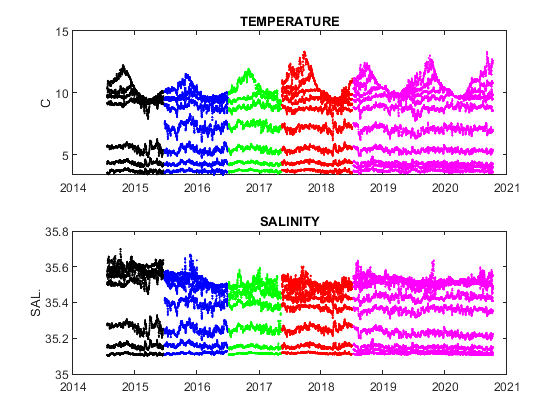

PDENfs1 = sw_pden(Sfs1,Tfs1,Pfs1,0) - 1000;
PDENfs2 = sw_pden(Sfs2,Tfs2,Pfs2,0) - 1000;  
PDENfs3 = sw_pden(Sfs3,Tfs3,Pfs3,0) - 1000;
PDENfs4 = sw_pden(Sfs4,Tfs4,Pfs4,0) - 1000;
PDENfs5 = sw_pden(Sfs5,Tfs5,Pfs5,0) - 1000;

figure(11)   %  graph of the data to show that it is all there!
clf;
subplot(2,1,1);
hold on; box on;
plot(JG , Tfs1, 'k.')
plot(JG , Tfs2, 'b.')
plot(JG , Tfs3, 'g.')
plot(JG , Tfs4, 'r.')
plot(JG , Tfs5, 'm.')

ylabel('C')
datetick
title('TEMPERATURE')

subplot(2,1,2);
hold on; box on;
plot(JG , Sfs1, 'k.')
plot(JG , Sfs2, 'b.')
plot(JG , Sfs3, 'g.')  
plot(JG , Sfs4, 'r.')
plot(JG , Sfs5, 'm.')

ylabel('SAL.')
datetick
title('SALINITY')
    
set(gcf,'PaperUnits','centimeters','PaperPosition',[0 0 16 12]*1.5)   
print('-dpng',[grdatdir 'otherfigure' filesep  'RTEBmerged_beforegrid_check1'])

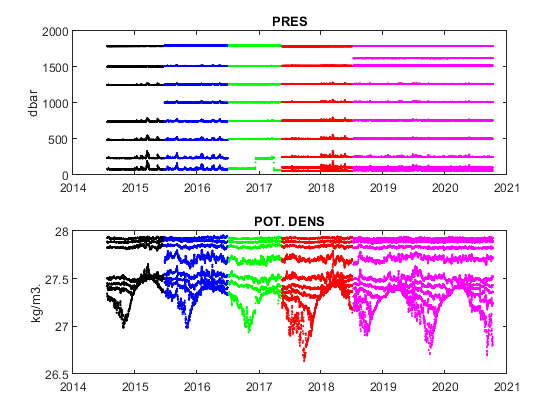


figure(10)   %  graph of the data to show that it is all there!
clf;
subplot(2,1,1);
hold on; box on;
plot(JG , Pfs1, 'k.')
plot(JG , Pfs2, 'b.')
plot(JG , Pfs3, 'g.')  
plot(JG , Pfs4, 'r.')  
plot(JG , Pfs5, 'm.')  
ylabel('dbar')
datetick
title('PRES')   

subplot(2,1,2);
hold on; box on;
plot(JG , PDENfs1, 'k.')
plot(JG , PDENfs2, 'b.')
plot(JG , PDENfs3, 'g.')  
plot(JG , PDENfs4, 'r.')
plot(JG , PDENfs5, 'm.')
ylabel('kg/m3.')
datetick
title('POT. DENS')   

set(gcf,'PaperUnits','centimeters','PaperPosition',[0 0 16 12]*1.5)   
print('-dpng',[grdatdir 'otherfigure' filesep  'RTEBmerged_beforegrid_check2'])


% all the matrices for the deployments stacked together
Pfs     = [Pfs1;Pfs2;Pfs3;Pfs4;Pfs5];
Sfs     = [Sfs1;Sfs2;Sfs3;Sfs4;Sfs5];
Tfs     = [Tfs1;Tfs2;Tfs3;Tfs4;Tfs5];

% order the matrices at every time step to avoid too many NaNs creeping in
% 2004 removed....
P_sort = NaN .* ones(size(Pfs)); T_sort = NaN .* ones(size(Tfs)); S_sort = NaN .* ones(size(Sfs));
j = 1;
for ii = 1: length(JG)
    [P_variable, ix] = sort(Pfs(:, ii));
    P_sort(:,j) = Pfs(ix,ii);
    T_sort(:,j) = Tfs(ix,ii);
    S_sort(:,j) = Sfs(ix,ii);
    j = j + 1;
end

% removing unused rows of the sorted matrices
Pfss = nan(size(Pfs));
Tfss = nan(size(Pfs));
Sfss = nan(size(Pfs));
i = 1; j = 1;
for i = 1: length(P_sort(:,1))
    ix = find(isnan(P_sort(i,:)));
    if length(ix) < length(JG)
        Pfss(j,:) = P_sort(i, :);
        Tfss(j,:) = T_sort(i, :);
        Sfss(j,:) = S_sort(i, :);
        j = j + 1;
    end
end

clear Pfs1 Pfs2 Pfs3 Pfs4 Pfs5
clear Sfs1 Sfs2 Sfs3 Sfs4 Sfs5
clear Tfs1 Tfs2 Tfs3 Tfs4 Tfs5

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## 4. GRIDDING

This is the most contentious part of this code.  I have edited the gridding function con_tprof0.m to select the pressure grid at every time step rather than just take the the common range throught out the whole time series. This then carries out the gridding at every 12 hour time step based on the merged data matrix.  I also forced the gridding only to run when there are at least 4 data points.  See notes on the griddig in the document written on this project! Gridding is the process of vertically interpolating the T, S and P data onto a regular pressure grid. 

pmin = ceil(min(Pfss)/20) * 20;
pmax = floor(max(Pfss)/20) * 20;
    
if gridding == 2 % using climatological profiles
    outputfile = ['RTEB_merg_' TS_CLIMATOLOGY_TP ' ' TS_CLIMATOLOGY '_' lastyeardata ];
    if strcmp(TS_CLIMATOLOGY_TP,'annual')
        disp('con_tprof0_annual')
        [TGfs, SGfs] = con_tprof0_annual(Tfss, Sfss, Pfss, pgg', 0*ones(1, size(Tfss, 2)), int_step, TSclim, ...
                                          TS_CLIMATOLOGY,TS_CLIMATOLOGY_NAME);
    elseif strcmp(TS_CLIMATOLOGY_TP,'seasonal')
        disp('con_tprof0_monthly')
        [TGfs, SGfs] = con_tprof0_monthly(Tfss, Sfss, Pfss, pgg', GTV(:,2), int_step, TSclim,TS_CLIMATOLOGY, ...
                                          TS_CLIMATOLOGY_NAME );
    end
   
elseif gridding == 1 % linear interpolation   

outputfile = ['RTEB_merg_linear_interp' '_' lastyeardata ];
TGfs = nan(length(pgg),length(JG));
SGfs = nan(length(pgg),length(JG)); 
for ijj=1:length(JG)
    itok = find(~isnan(Tfss(:,ijj)));
    isok = find(~isnan(Sfss(:,ijj)));
    if length(itok)>1
        TGfs(:,ijj) = interp1(Pfss(itok,ijj),Tfss(itok,ijj),pgg) ; 
    end
    if length(isok)>1
        SGfs(:,ijj) = interp1(Pfss(isok,ijj),Sfss(isok,ijj),pgg) ;     
    end
end
end 



## Apply correction for 2017 data to EB mooring

[Tfs,Sfs,Pfs,TGfs,SGfs] = extrap_missing_data(pathosnap,Tfs,Sfs,Pfs,TGfs,SGfs,JG,pgg);

Error: File: extrap_missing_data.mlx Line: 214 Column: 115
This statement is incomplete.

## Save data

disp(['saving: ' outputfile '.mat'])
% Alloacte variables into a structure
RTEB_merg.JG     = JG;
RTEB_merg.Tfs    = Tfs;
RTEB_merg.Sfs    = Sfs;
RTEB_merg.Pfs    = Pfs;
RTEB_merg.PGfs    = pgg';    
RTEB_merg.TGfs   = TGfs;
RTEB_merg.SGfs   = SGfs;
if gridding == 2 % using climatological profiles    
    RTEB_merg.TS_CLIMATOLOGY   = TS_CLIMATOLOGY;
    RTEB_merg.TS_CLIMATOLOGY_TP= TS_CLIMATOLOGY_TP;
    RTEB_merg.TS_CLIMATOLOGY_NAME= TS_CLIMATOLOGY_NAME;
    RTEB_merg.clim_file        = TSclim;
end    

stddy_tol  = 10; % 4
std_win    = 3.5; % 3.5 * std of the time series
[nloop]    = 5; % 5
graphics   = 'y';
temp = []; salinity = [];


### despike time series



    for i = 1 : length(TGfs(:,1))   % loop through each depth level
        
        [temp(i,:),dx,ndx] = ddspike(TGfs(i,:),[-std_win*nanstd(TGfs(i,:)),...
            std_win*nanstd(TGfs(i,:))],stddy_tol,[nloop],'y',NaN);
        [salinity(i,:),dx,ndx] = ddspike(SGfs(i,:),[-std_win*nanstd(SGfs(i,:)),...
            std_win*nanstd(SGfs(i,:))],stddy_tol,[nloop],'y',NaN);
    end
    
[m,n] = size(TGfs);
TG_east = NaN * ones(m,n); SG_east = NaN * ones(m,n);

% GDM, 9/4/2013
% Need to interpolate horizontally over nans but...
% Don't want to create fake values above knocked down moorings
% So select a depth below which, interpoation happens

idepth = depthminforhoriz_interp; % multiples of 20
I = find(pgg == idepth);

% copy the top idepth into the new file
% no temporal interpolation
SG_east([1:I-1],:)=SGfs([1:I-1],:);
TG_east([1:I-1],:)=TGfs([1:I-1],:);

% this piece of code has the ability to create spurious values of T & S ** tk
% how large are the temporal gaps in the time series ?
% linear should only be used for small gaps.

%     i = 7; j = 7; % PG(7) = 120;
%     i = 11; j = 11; % PG(11) = 120;

i = I; j = I;
for i = I: length(pgg) % for each depth

    % locate all non nan values in the despiked temperature
    it = find(~isnan(temp(i,:)));
    if length(it) < 2
        continue
    end
    % locate all non nan values in the despiked salinity
    is = find(~isnan(salinity(i,:)));
    % interpolate in time over the missing data
    SG_east(i,:) = interp1(JG(is), salinity(i, is), JG);
    % interpolate in time over the missing data
    TG_east(i,:) = interp1(JG(it), temp(i, it), JG);

    %j = j + 1;
end
    
figure;
% spurious values created in the interpolation?
hold on; grid on; box on;
plot(SG_east,TG_east,'k')
plot(SGfs,TGfs,'r--')


### ALLOCATE VARIABLES AND SAVE

RTEB_merg.TGfs2= TG_east;
RTEB_merg.SGfs2= SG_east;
RTEB_merg.comment{1,1}= 'JG -- julian day';
RTEB_merg.comment{2,1}= 'Tfs -- original stacked Temperature data from the deployments';
RTEB_merg.comment{3,1}= 'Sfs -- original stacked salinity data from the deployments ';
RTEB_merg.comment{4,1}= 'Pfs -- original stacked Pressure data from the deployments';    
RTEB_merg.comment{5,1}= 'PGfs -- pressure grid ';
RTEB_merg.comment{6,1}= 'TGfs -- temperature interpolated onto the pressure grid (PGfs)';
RTEB_merg.comment{7,1}= 'SGfs -- salinity interpolated onto the pressure grid (PGfs)';
RTEB_merg.comment{8,1}= 'TGfs2 -- temperature interpolated onto the time grid (JG) after despiking';  
RTEB_merg.comment{9,1}= 'SGfs2 -- salinity interpolated onto the time grid (JG) after despiking';  

save([grdatdir outputfile],'RTEB_merg');

###  6. PLOTTING THE GRIDDED AND MERGED PROFILES 

close all
figure(1); clf
subplot(3,1,1)
contourf(JG , pgg, TGfs,28,'LineColor','none'); 
hold on
[c,h]=contour(JG , pgg, TGfs,[2 4 6 8 10 12 14],'LineColor','k','LineWidth',0.25); 
clabel(c,h,'LabelSpacing',500,'Color','w')
axis ij
datetick('x'); 
ylabel('Pressure')
title('RTEB BEFORE DESPIKING AND INTERPOLATION')

caxis([floor(min(min(TGfs))) ceil(max(max(TGfs)))]);
C = colorbar;
C.Label.String = 'Conservative Temperature (^{o} C)';
C.Ticks=[floor(min(min(TGfs))):1:ceil(max(max(TGfs)))];
C.TickLength=0.05;

subplot(3,1,2)
contourf(JG , pgg, temp,28,'LineColor','none'); 
hold on
[c,h]=contour(JG , pgg, temp,[2 4 6 8 10 12 14],'LineColor','k','LineWidth',0.25);
clabel(c,h,'LabelSpacing',500,'Color','w')
axis ij
datetick; 
ylabel('Pressure');
title('AFTER DESPIKING')

caxis([floor(min(min(temp))) ceil(max(max(temp)))]);
C = colorbar;
C.Label.String = 'Conservative Temperature (^{o} C)';
C.Ticks=[floor(min(min(temp))):1:ceil(max(max(temp)))];
C.TickLength=0.05;

subplot(3,1,3)
contourf(JG , pgg, TG_east,28,'LineColor','none'); 
hold on
[c,h]=contour(JG , pgg, TG_east,[2 4 6 8 10 12 14],'LineColor','k','LineWidth',0.25); 
clabel(c,h,'LabelSpacing',500,'Color','w')
axis ij
datetick; ylabel('Pressure')
title('AFTER DESPIKING AND INTERPOLATION')

caxis([floor(min(min(TG_east))) ceil(max(max(TG_east)))]);
C = colorbar;
C.Label.String = 'Conservative Temperature (^{o} C)';
C.Ticks=[floor(min(min(TG_east))):1:ceil(max(max(TG_east)))];
C.TickLength=0.05;

set(gcf,'PaperUnits','centimeters','PaperPosition',[0 0 16 12]*1.5)
print('-dpng',[grdatdir outputfile '_temperature'])

figure(2);clf
subplot(3,1,1)
contourf(JG , pgg, SGfs,28,'LineColor','none'); 
hold on
[c,h]=contour(JG , pgg, SGfs,[35 35.2 35.4 35.6],'LineColor','k','LineWidth',0.25); 
clabel(c,h,'LabelSpacing',500,'Color','w')
axis ij
datetick('x'); 
ylabel('Pressure')
title('RTEB BEFORE DESPIKING AND INTERPOLATION')

caxis([round(min(min(SGfs)),1) round(max(max(SGfs)),1)]);
C = colorbar;
C.Label.String = 'Absolute Salinity (g kg^{-1})';
C.Ticks=[round(min(min(SGfs)),1):0.1:round(max(max(SGfs)),1)];
C.TickLength=0.03;

subplot(3,1,2)
contourf(JG , pgg, salinity,28,'LineColor','none'); 
hold on
[c,h]=contour(JG , pgg, salinity,[35 35.2 35.4 35.6],'LineColor','k','LineWidth',0.25); 
clabel(c,h,'LabelSpacing',500,'Color','w')
axis ij
datetick; ylabel('Pressure')
title('AFTER DESPIKING')

caxis([round(min(min(salinity)),1) round(max(max(salinity)),1)]);
C = colorbar;
C.Label.String = 'Absolute Salinity (g kg^{-1})';
C.Ticks=[round(min(min(salinity)),1):0.1:round(max(max(salinity)),1)];
C.TickLength=0.03;

subplot(3,1,3)
contourf(JG , pgg, SG_east,28,'LineColor','none'); 
hold on
[c,h]=contour(JG , pgg, SG_east,[35 35.2 35.4 35.6],'LineColor','k','LineWidth',0.25); 
clabel(c,h,'LabelSpacing',500,'Color','w')
axis ij
datetick; ylabel('Pressure')
title('AFTER DESPIKING AND INTERPOLATION')

caxis([round(min(min(SG_east)),1) round(max(max(SG_east)),1)]);
C = colorbar;
C.Label.String = 'Absolute Salinity (g kg^{-1})';
C.Ticks=[round(min(min(SG_east)),1):0.1:round(max(max(SG_east)),1)];
C.TickLength=0.03;

set(gcf,'PaperUnits','centimeters','PaperPosition',[0 0 16 12]*1.5)   
print('-dpng',[grdatdir outputfile '_salinity'])

PDENGfs = sw_pden(SGfs,TGfs,pgg',0);
pden = sw_pden(salinity,temp,pgg',0);   
PDENG_east = sw_pden(SG_east,TG_east,pgg',0);   
figure(3);clf
subplot(3,1,1)
contourf(JG , pgg, PDENGfs,10); axis ij
caxis([min(PDENGfs(:)) max(PDENGfs(:))])
datetick; ylabel('POT. DENS.')
title('RTEB BEFORE DESPIKING AND INTEROLATION')
subplot(3,1,2)
contourf(JG , pgg, pden,10); axis ij
  caxis([min(PDENGfs(:)) max(PDENGfs(:))])
datetick; ylabel('POT. DENS.')
title('AFTER DESPIKING')
subplot(3,1,3)
contourf(JG , pgg,PDENG_east,10); axis ij
caxis([min(PDENGfs(:)) max(PDENGfs(:))])
datetick; ylabel('POT. DENS.')
title('AFTER DESPIKING AND INTERPOLATION')
set(gcf,'PaperUnits','centimeters','PaperPosition',[0 0 16 12]*1.5)   
print('-dpng',[grdatdir outputfile '_potdens'])
    
% ------------- MAKE MERGED DAT ONLY FIGURE -----------------------------

% TEMPERATURE
figure;
ax(1)=subplot(2,1,1)

x=JG;
y=pgg;
z=TG_east;
[c,h]=contourf(x,y,z,100,'LineColor','none');
caxis([ceil(min(min(TG_east))) floor(max(max(TG_east)))]);
C = colorbar;
C.Label.String = 'Conservative Temperature (^{o} C)';
C.Ticks=[floor(min(min(TG_east))):1:ceil(max(max(TG_east)))];
C.TickLength=0.03;
hold on
[c,h]=contour(x , y, z,[2 4 6 8 10 12 14],'LineColor','k','LineWidth',0.25);
clabel(c,h,'LabelSpacing',500,'Color','w')
xlabel(gca,'Year');
ylabel(gca,'Pressure (m)');
[Y,~,~]=datevec(JG);
date1=datenum(min(Y),1,1);
date2=datenum(max(Y),1,1);
% xtick(gca,[date1:365:date2]);
% xticklabels(gca,datestr([date1:365:date2],'YYYY'));
datetick('x','Keeplimits');
axis ij
title('Rockall Trough Eastern Boundary Gridded Temperature')
cmap=cmocean('Thermal')
colormap(ax(1),cmap)

% SALINITY
ax(2)=subplot(2,1,2)
x=JG;
y=pgg;
z=SG_east;
[c,h]=contourf(x,y,z,12,'LineColor','none');
caxis([round(min(min(z)),1) round(max(max(z)),1)]);
C = colorbar;
% cmap=colormap('parula');
cmap=cmocean('Haline')
colormap(ax(2),cmap);
C.Label.String = 'Absolute Salinity (g kg^{-1})';
C.Ticks=[round(min(min(z)),1):0.1:round(max(max(z)),1)];
C.TickLength=0.03;
hold on
[c,h]=contour(JG , pgg, SGfs,[35.2 35.4 35.6],'LineColor','k','LineWidth',0.25); 
clabel(c,h,'LabelSpacing',500,'Color','w')
xlabel(gca,'Year');
ylabel(gca,'Pressure (m)');
% SORT LABELS
[Y,~,~]=datevec(JG);
date1=datenum(min(Y),1,1);
date2=datenum(max(Y),1,1);
datetick('x','Keeplimits');
axis ij
title('Rockall Trough Eastern Boundary Gridded Salinity')

width=35; height=20; FS=12; FN='Arial';
set(gca,'fontsize', FS, 'FontName',FN);
set(gcf,'units','centimeters','position',[5 5 width height])
print('-dpng',[grdatdir outputfile '_S_all'])

DENSITY

figure;
x=JG;
y=pgg;
z = gsw_rho(SG_east,TG_east,0);   
[c,h]=contourf(x,y,z,100,'LineColor','none');
% cmocean('dense',100);
% colormap(parula);
xlabel(gca,'Year');
ylabel(gca,'Pressure (m)');
% SORT LABELS
[Y,~,~]=datevec(JG);
date1=datenum(min(Y),1,1);
date2=datenum(max(Y),1,1);
xticks(gca,[date1:365:date2]);
xticklabels(gca,datestr([date1:365:date2],'YYYY'));
axis ij
caxis([round(min(min(z)),1) round(max(max(z)),1)]);
C = colorbar;
C.Label.String = 'Potential density (kg/m^{3})';
C.Ticks=[round(min(min(z)),1):0.1:round(max(max(z)),1)];
C.TickLength=0.03;

width=25; height=20; FS=14; FN='Arial';
set(gca,'fontsize', FS, 'FontName',FN);
set(gcf,'units','centimeters','position',[5 5 width height])

print('-dpng',[grdatdir outputfile '_RHO_all'])
% print(gcf, '-dpng',[basedir '/Figures/East/Density']);
